**1 Segmentierung, Schwellwerte, Histogramme (ca. 20-30 Min)**

Der Ordner „Muttern“ enthält mehrere Bilder von Muttern, die im Durchlichtverfahren erstellt worden sind. Ziel ist es, die Anzahl der Muttern im Bild zu bestimmen. Lesen sie zunächst das Bild "Muttern_2_1.png" ein (`imread`).

 a=imread("Muttern_2_1.png" )

Error using imread>get_full_filename (line 567)
File "Muttern_2_1.png" does not exist.

Error in imread (line 374)
    fullname = get_full_filename(filename);

- Nutzen Sie die Funktion h`istogram`, um die Grauwertverteilung des Bildes darzustellen.

- Segmentieren Sie die Muttern mit Hilfe der Funktion `imbinarize`. Bestimmen Sie einen Schwellwert anhand des Histogramms. Lassen Sie sich das erzeugte Binärbild anzeigen.

- Die segmentierte Fläche ist jetzt hell dargestellt. Wie kann der Code einfach verändert werden, dass statt des Hintergrundes die Mutter segmentert wird?

- Nutzen Sie die Funktion `imoverlay`, um die segmentierte Fläche im ursprünglichen Bild farbig darzustellen.

- Kann aus dem Mittelwert des Bildes (`mean`) auf die Anzahl der Muttern im Bild geschlossen werden? Verwenden Sie dazu die verschiedenen Bilder im Ordner "Muttern". Untersuchen Sie auch das Binärbild. 

- Nutzen Sie die Funktion `bwconncomp`, um die Anzahl der verbundenen Regionen im Binärbild, also die Anzahl der Muttern, zu bestimmen.

- Im Ordner befinden sich einige Bilder, bei denen die Aufnahmeparameter nicht korrekt eingestellt wurden, oder die Muttern nicht ideal platziert wurden. Diskutieren Sie die Robustheit der Verfahren gegenüber solchen Veränderungen!

**2 Grenzen von Schwellwertoperationen, inhomogene Punktoperatoren (ca. 30-45 Min)**

Die Segmentierung der Muttern stellte sich als verhältnismäßig einfach heraus. Nun schauen wir uns ein etwas schwierigeres Beispiel an, und zwar die Segmentierung eines Pumpengehäuses. Die zugehörigen Bilder finden Sie im Ordner „Pumpengehäuse“.

- Versuchen Sie analog zur Aufgabe 1 das Pumpengehäuse aus „Bild 1“ mit Hilfe eines Schwellwertoperators zu segmentieren. Welche Probleme treten bei der Segmentierung auf?

- Nutzen Sie nun das „Bild 2“, um eine Subtraktion des Hintergrunds durchzuführen. Nach der Subtraktion können Sie wiederum einen Schwellwert zur Segmentierung anwenden. Vergleichen Sie auch das Histogramm vor und nach der Subtraktion.

- Inwiefern wird die Segmentierung des Pumpengehäuses durch das Hintergrundbild vereinfacht? Warum ist diese Lösung weiterhin nicht ideal, und wie könnten Sie das Problem möglichst einfach beheben?

- Eine bessere Lösung bietet in diesem Fall die Maske in „Bild 3“. Nutzen Sie sie, um das Pumpengehäuse mit Hilfe von Bildarithmetik (`immultiply`) aus dem Originalbild auszuschneiden, und beurteilen Sie das Ergebnis. Funktioniert dieses Verfahren auch, wenn Sie statt des Pumpengehäuses in „Bild 1“ das „Bild 4“ verwenden?

**Bonusaufgabe:** Subtrahieren Sie „Bild 1“ und „Bild 4“ und markieren Sie die Unterschiede mittels `imbinarize`. Was für Informationen könnten Sie aus diesem Bild entnehmen?

**3 Segmentierung, Morphologische Operationen, LookUp-Tables (ca. 45-60 Min)**

Das Pumpengehäuse war nicht allein auf Basis der Grauwerte zu segmentieren. Nun schauen wir uns einen Fall an, in dem zwar ein Schwellwertoperator zur Segmentierung genutzt werden kann, jedoch eine Nachbearbeitung mittels morphologischen Operatoren notwendig ist. Nutzen Sie das Bild „Leiterplatte“.

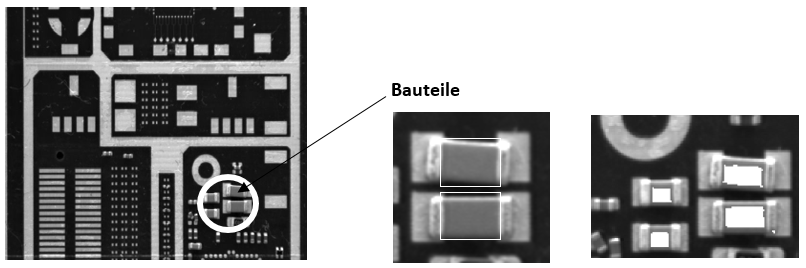

- Erstellen Sie ein Skript, das die Flächen der vier größeren Bauteile (Nur die im Bild weiß umrandete Fläche in der Mitte der Bauteile, nicht die Kontakte links und rechts an den Bauteilen) unabhängig von der Lage der Bauteile segmentiert. Nutzen Sie die bisher kennengelernten Werkzeuge, um eine Segmentierung mittels Schwellwertoperation durchzuführen. Da `imbinarize` nur einen Schwellwert nutzt und deshalb graue Flächen nicht gleichzeitig von hellen und dunklen Flächen trennen kann, können Sie zwei Binärbilder mit unterschiedlichen Schwellwerten erzeugen und anschließend voneinander subtrahieren.

- Entfernen Sie übrig bleibende Artefakte anschließend mit Hilfe von morphologischen Funktionen.

**Bonusaufgabe:** Heben Sie die Flächen der Bauteile im Originalbild hervor, indem Sie sie weiß markieren (wie im rechten Bild).

- Lassen Sie sich das Histogramm zum Originalbild „Leiterplatte“ anzeigen. Wie Sie sehen, wird das vorhandene Spektrum an Grauwerten schlecht ausgenutzt. Der Kontrast in den hellen und dunklen Bereichen ist daher jeweils nicht optimal. Nutzen Sie `imadjust,` um den Kontrast einmal in dunklen und einmal in hellen Regionen zu verbessern, d.h. die Grauwertunterschiede im relevanten Bereich besser wahrnehmbar zu machen. Vollziehen Sie Ihre Auswahl nach, indem Sie den funktionalen Zusammenhang zwischen Originalgrauwert und Ergebnisgrauwert skizzieren!

- Finden Sie auch eine Funktion, die den Kontrast gleichzeitig sowohl in den hellen als auch in den dunklen Bereichen verbessert? Wie könnte der funktionale Zusammenhang in diesem konkreten Fall aussehen? Diskutieren Sie!